%% Load data and visualize
addpath("routines\");

load("data/ecgpvc.mat");
% visualpvc(ecgpvc);

## Take five representative ectopic beats

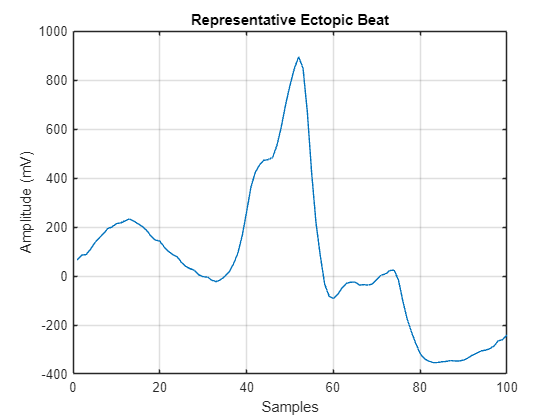

% Manually take the peaks
peaks = [39.25, 41.12, 45.39,47.345 ,49.1 ];
fs = 200;
peak_samples = peaks * fs;
sample_window = 50;

window_accum_values = zeros(sample_window*2, 1);
for i = peak_samples
    window = ecgpvc(i-sample_window:i+sample_window-1);
    window_accum_values = window_accum_values + window;
end

representative_beat = window_accum_values / length(peak_samples);

figure;
plot(representative_beat);
title('Representative Ectopic Beat');
xlabel('Samples')
ylabel('Amplitude (mV)')
grid on;

## Xcorr between ECG signal and Representative ectopic Beat

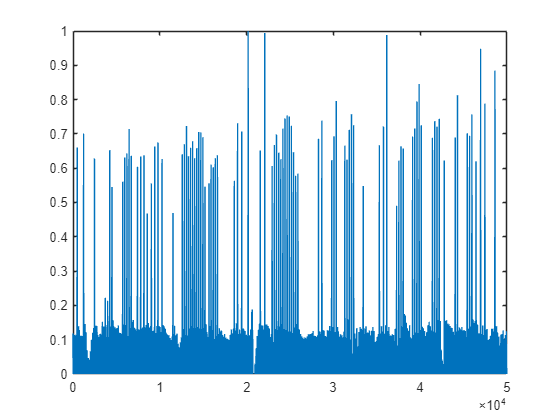

% Normalize signals

[corr, lags] = xcorr(ecgpvc, representative_beat);
trimmed_corr = corr(lags >= 0);

% Normalize corr
normalized_trim_corr = trimmed_corr / max(trimmed_corr);

figure()
plot(normalized_trim_corr);
ylim([0 1])

## Apply threshold 

## Islocalmax

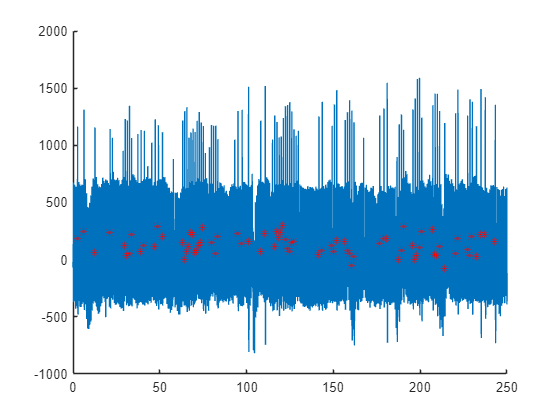


% Define the time
time = linspace(0, 250, 50000);

% Apply the threshold
threshold = 0.4;

% Find indxs above the threshold
idxs = find(normalized_trim_corr >= threshold);

% Find local maximum values of idxs
center_idx = find(islocalmax(normalized_trim_corr(idxs)) == 1);
max_samples = idxs(center_idx);
plot_local_max(ecgpvc, time, max_samples);

## findpeaks

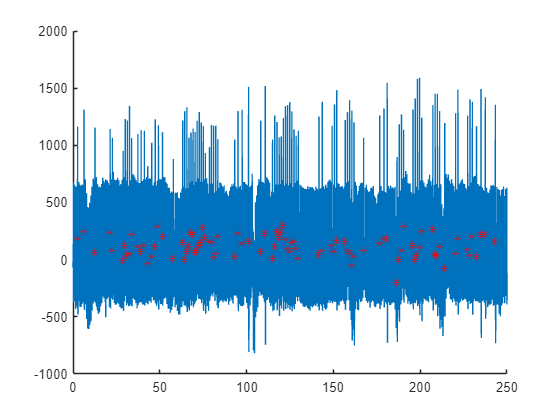

% Define the time
time = linspace(0, 250, 50000);

% Apply the threshold
threshold = 0.4;

% Find indxs above the threshold
[~, idxs] = findpeaks(normalized_trim_corr, "MinPeakHeight", 0.4);

plot_local_max(ecgpvc, time, idxs);

## Exercise 2

clear all;
clc;

load("data/ecgf.mat");
fs = 1000; %Hz


### Plot the data

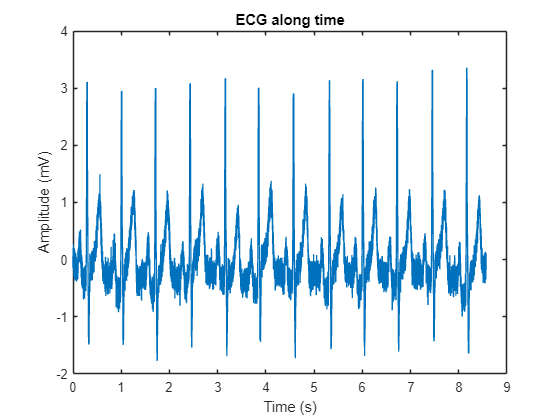

time = linspace(0, length(ecgf)/fs, length(ecgf));

figure;
plot(time, ecgf);
xlabel('Time (s)');
ylabel('Amplitude (mV)');
title('ECG along time');

## Show noise

Y = fft(ecgf);
N = length(ecgf);  % Number of samples
f = (0:N-1) * (fs / N);  % Frequency vector for single-sided spectrum

Y = Y(1:N/2);  % Keep only the first half (positive frequencies)
f = f(1:N/2)

f =          0    0.1167    0.2334    0.3501    0.4669    0.5836    0.7003    0.8170    0.9337    1.0504    1.1671    1.2838    1.4006    1.5173    1.6340    1.7507    1.8674    1.9841    2.1008    2.2176    2.3343    2.4510    2.5677    2.6844    2.8011    2.9178    3.0345    3.1513    3.2680    3.3847    3.5014    3.6181    3.7348    3.8515    3.9683    4.0850    4.2017    4.3184    4.4351    4.5518    4.6685    4.7852    4.9020    5.0187    5.1354    5.2521    5.3688    5.4855    5.6022    5.7190


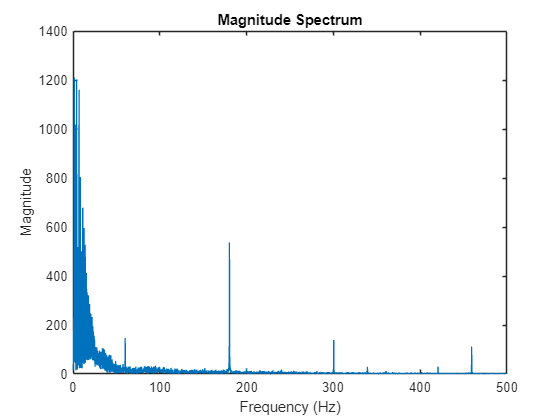


magnitude = abs(Y);

plot(f, magnitude);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Magnitude Spectrum');